## Input runData and modelData

%clear runData modelData;

% Settings to run model
runData.filename = 'testgif.gif';
runData.runType = 'time';
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.05;          % mesh size: default hmax = 0.05
runData.dataset = 'Diff_driven';  
runData.nEquations = 1;      % number of PDE's in system

% Load material properties and sources
[modelData.Diff,modelData.Diff_info] = s4_loadProperties_EK(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = [1,2,2]; % define differently if different material per face (# faces = 2, so 2 elements)

% Source assignment to model domains
modelData.sourceIDs = [1,2,2]; % define differently if different source term (more heat /concentration)
modelData.fixedSource = [0;0;0]; % Source terms, is zero for both subdomains. Change if different source terms. 
modelData.SourceValue = 7.97*10^9; % maxiumum possible #NPs/cm3; % #/injection concentration of NPs per injection volume ~1.25E+12 #NPs/injection

## 1+2: Create model, geometry and mesh

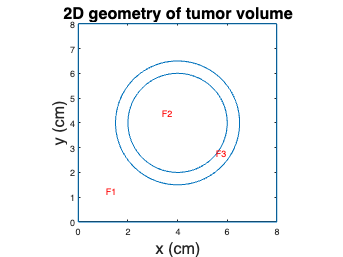

tic
% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,~,centretumor,diametertumor] = t2_createGeometry2D(model,runData); % default = (circle tumor + part breast)

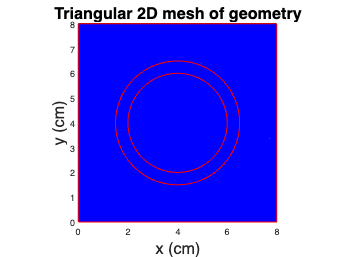

% Generate mesh
[model] = s3_createMesh2D(model,runData);

toc

Elapsed time is 1.810348 seconds.


## 4: Set BC, IC and time scale

tic
% Boundary conditions:      only applicable for outer boundaries
runData.nBCs.neumann = 1;   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('edge',1:4,'q',0,'g',0); % flux breast [#NPs/m2*s] % must depend on conc. present to not become negative. Which BC?
%runData.BCs.neumann(2) = struct('edge',[2 4],'q',0,'g',modelData.flux); %6 flux tumor [#NPs/m2*s]
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('edge',[],'u',0);     % [] means isempty

% Initial conditions
[modelData.x0, modelData.y0, noSeeds] = t4_3_XZ_seedlocationssquare(diametertumor,centretumor); % the coordinates of the centre of the seeds
runData.nICs = 2;                  % necessary to define if multiple initial conditions different per face
modelData.Cinit_tumor = @(location)Cinit_NP2(location,modelData.x0,modelData.y0,modelData.SourceValue);
runData.IC(1) = struct('u',0,'Face',1);   % initial concentration of NPs in body = 0 [#NPs/m3]
runData.IC(2) = struct('u',modelData.Cinit_tumor,'Face',2:3);    % initial concentration of NPs in tumor: equation zero everywhere except at injection locations [#NPs/m3]. Function @Cinit_NP2 gives C_init at meshnodes near seed location 

% Load BC and IC
[model] = s4_2_loadBCIC(model,modelData,runData);

% Time scale
h = 24*17; % number of hours after injection % default total time  = 17*24 h
runData.timePoints = 0:1:h;  % default stepsize = 1 h % compute in hours because diffusion terms have been changed to m2/h instead of m2/s (see loadXS_EK)
%toc

## 3+5: Solve system of PDE 

tic
% Solve PDE model
[~,results] = s5_NPDiffusion2D(model,modelData,runData); % using FEM to solve system of PDE to calculate for each time step the distribution of the NPs
modelData.Cresults = results.NodalSolution;              % results of solvepde function. Matrix with concentration of NPs for each meshnode (rows) per timestep (columns)      
Cresults = modelData.Cresults;
toc

Elapsed time is 182.822396 seconds.


solmin = min(modelData.Cresults);

## 6: Results: max, min average through tumour

% Calculate maximum, minimum and average results over time
modelData.solMin = min(modelData.Cresults);
modelData.solMax = max(modelData.Cresults);
r = [2 , 2.5 , 3.5];  % Radius of tumour volume taken into account
[modelData] = s6_2_Cresults_average(model,modelData,r(1),r(2),r(3),centretumor(1)); % C values (max,min,average) in GTV

averageC_GTV = 1.7106e+08

minC_GTV = 0.0087

maxC_GTV = 1.9753e+09

averageC_PTV = 6.1288e+03

minC_PTV = 9.4575e-13

maxC_PTV = 6.4117e+05

averageC_1cm = 6.2225e-06

minC_1cm = 1.3474e-19

maxC_1cm = 7.2719e-04


[averageC,minC,results_order] = s6_2_Cresults_time(model,modelData,r(1),centretumor(1)); % averageT and minT only in tumour area
solMax = modelData.solMax;                                                 % maxT in total area


t_back37 =

  1×0 empty double row vector



## 6: Plots: Intersection and distribution profile

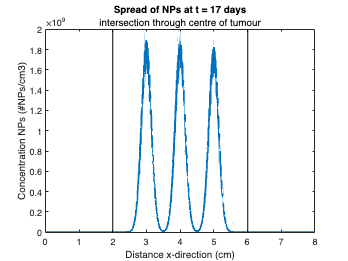

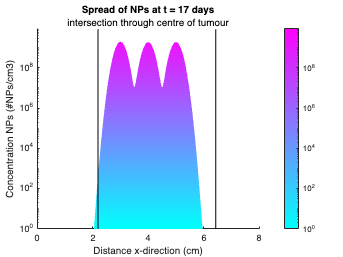

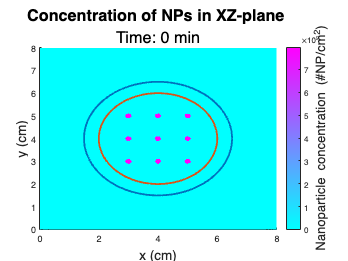

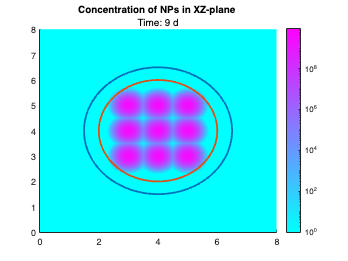

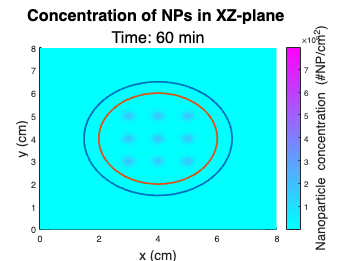

model = s6_results_plots2D(model,modelData,runData);

%s6_plotPDESolution(model,T,runData) %% --> not yet fixed for 3D

## 6: Plot: Tmax, Tav, Tmin over time

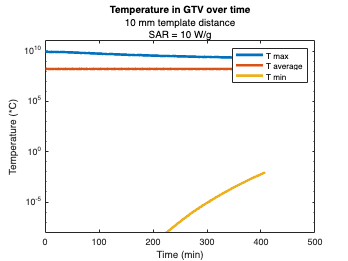

figure
plot(runData.timePoints,modelData.solMax,'LineWidth',3)
hold on
plot(runData.timePoints,averageC,'LineWidth',3)
plot(runData.timePoints,minC,'LineWidth',3)
set(gca,'YScale','log')
ylim([10^-8 10^11])
title('Temperature in GTV over time')
txt = {'10 mm template distance','SAR = 10 W/g'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Time (min)") 
legend("T max","T average","T min")

## Save results

save Cresults_D_min Cresults solMax averageC minC Xnodes Ynodes

function Cinit_tumor = Cinit_NP2(location,x0,y0,SourceValue)
        % heaviside gives 0 if the equation of radius - the circle is smaller than 0 (location is outside the circle)
        % and gives 1*Sourcevalue for all locations within the circle
        % third term represents a normal distribution over x and y, resulting in a smooth distribution
        % with the coordinations of the node as the maximum of the Gaussian peak (=1).
        % This needs to be multiplied with the value of the concentration of the injection
        r = 0.1;            % radius that the seed should have
        R = r^2;      % radius of heaviside circle 
        Near_seed = 0;
        for i = 1:length(x0)
        Cinit_seed = (heaviside(R-((location.x-x0(i)).^2+(location.y-y0(i)).^2))); %.*exp(-(location.x-x0(i)).^2./sigmax^2-(location.y-y0(i)).^2./sigmay^2); 
        Near_seed = Near_seed + Cinit_seed;
        end  
        Cinit_tumor = Near_seed.*SourceValue;
        % SOME FIST RULES:
        % 1. Smaller diameter seed: smaller sigma, smaller radius IC, (larger caxis: visibility)
        % 2. Smaller solmin: smaller Hmax, smaller stepsize, smaller sigma
        % 3. Stepsize and hmax dont have influence on diameter seed
        % 4. Sigma cannot be smaller than Hmax, because spread cannot be smaller than mesh element
        % 5. 
end